# Direct Channel Estimation - Phase 2

**Based on the paper:** Channel Estimation for Intelligent Reflecting Surface Assisted Multiuser Communications: Framework, Algorithms, and Analysis 

 or 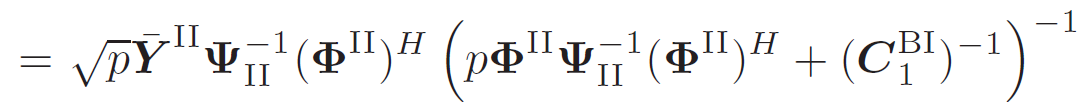

function [channel,MSE] = channelPrisEstimation(sys, channel, estimation, wo_noise, pwr)

    H = channel.H;
    G = channel.G;
    F = channel.F;
    H_est = channel.H_est;
    Betak = channel.Hkloss;

    noise_dbm = estimation.noise_dbm;
    T1 = estimation.T1_min;
    T0 = estimation.T0_min;

    K = sys.n_tx;
    M = sys.n_rx;
    Nc = sys.Nc;
    PWR = sys.PWR;
    
    % Power Normalization -----------------------------------
    sigma2_nest = (10^(noise_dbm/10));
    sigma2_s = PWR(pwr);
    
    %% ===============Phase I===========================
    F1=dftmtx(T1);
    Phi1 = F1(1:Nc,:); % pilots
    pilots = ones(1,T1)*sqrt(sigma2_s);
    noise = sqrt(sigma2_nest/2)*(randn(M,T1)+1j*randn(M,T1));
    factor = 1/(T1*sqrt(sigma2_s));

    G1_cov = M*channel.Gkloss*channel.Fkloss(1)*eye(Nc);
    G1_cov_inv = inv(G1_cov);

    Z_real = zeros(M,Nc,K);
    Z_est = zeros(M,Nc,K);
    if wo_noise
        %% With noise --------------------------------------
        for i = 1:K

%             err_0_1 = M*Betak(i)*sigma2_s/(Betak(i)*T0+sigma2_s);
%             Psi = err_0_1*ones(T1)+M*sigma2_s*eye(T1);
%             Psi_inv = inv(Psi);
%             temp3=Psi_inv*Phi1'*inv(Phi1*Psi_inv*Phi1'+G1_cov_inv);
% 
%             Y1 = G*diag(F(:,i))*Phi1*diag(pilots) + H(:,i)*pilots + noise;
%             Y1_refl = Y1 - H_est(:,i)*pilots;
%     
%             Gf_est = factor*Y1_refl*Phi1';
%             Z_est(:,:,i) = Gf_est;
%             Z_real(:,:,i) =  G*diag(F(:,i));
        end  
    
    else
        %% Without noise -----------------------------------
        Z_est = zeros(M,Nc,K);
        for i = 1:K
            Y1 = G*diag(F(:,i))*Phi1*diag(pilots) + H(:,i)*pilots + noise;
            Y1_refl = Y1 - H_est(:,i)*pilots;
    
            Gf_est = factor*Y1_refl*Phi1';
            Z_est(:,:,i) = Gf_est;
            Z_real(:,:,i) =  G*diag(F(:,i));
        end    
        
    end
    channel.Z = Z_est;
    ModZ2 = Z_real(:)'*Z_real(:);
    MSE = (Z_est(:)-Z_real(:))'*(Z_est(:)-Z_real(:))/ModZ2;
end